# **Investigate Effect of Cruise Altitude**

% House Keeping
clear
clc
close all

**Basic Parameters**

% Weight
W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

[T_0, c_0, P_0, rho_0] = atmosisa(0);    % Sea-level condition

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Mission Profile**

first cruise

for k = 1 : 100

% since the cruise condition is not specified in given mission
% profile, assume first cruise will be held in cruise-climb to
% maximise the fuel efficiency of the aircraft [Intro to Aero p.117]
h_cruise1 = 26000; % first cruise average altitude (ft)

[T_cruise1, c_cruise1, P_cruise1, rho_cruise1] = atmosisa(convlength(h_cruise1, 'ft','m'));
V_cruise1 = 0.83;

second cruise

h_cruise2 = 18000; % Cruise altitude (ft) for Lost Communications Missed Approach % Ref 5

V_cruise2 = convvel(400, 'kts', 'm/s'); % Assume cruise velocity 400 knots % Ref 5
[T_cruise2, c_cruise2, P_cruise2, rho_cruise2] = atmosisa(convlength(h_cruise2, 'ft','m'));
V_cruise2 = V_cruise2 ./ c_cruise2;

absolute ceiling

absCeiling = convlength(45000,'ft','m'); % Absolute Ceiling

loiter

h_loiter = convlength(5000, 'ft','m'); % Alternate altitude (m)

[T_loiter, c_loiter, P_loiter, rho_loiter] = atmosisa(h_loiter);

**Empirical Airplane Data**

AR = 7 + 0.03 * k; % Aspect ratio

AR_itr(k) = AR;

WR = 5.5;          % S_wet / S_ref         % Raymer p.40
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets        % Raymer p.40
LD_max = K_LD .* (AR_W) .^ 0.5; % L/D_max  % Raymer p.41

CD_0 = 0.023;  % Drag ceofficient at zero lift % Boeing 777-300ER
e = 0.85;      % Oswald/span efficiency factor % Boeing 777-300ER
CL_max_L = 2.69;             % Maximum lift coefficient in landing configuration
CL_max_TO = CL_max_L .* 0.8; % Maximum lift coefficient in take-off configuration
CL_max_C = 1.4;              % Maximum lift coefficient in cruise configuration

V_S = convvel(137, 'kts', 'm/s'); % Stall speed at sea level % Boeing 777-300ER
V_A = 1.3 * V_S;                  % Approach speed at sea level % Raymer p.110
V_TO = 1.2 * V_S;                 % Take off velocity (m/s)

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% BPR = 8.5;       % Bypass Ratio % Trent 972E-84 % Ref 17

**Calculate Fuel Fraction **

[W_f_0, W_i] = Wf_W0(h_cruise1, h_cruise2, V_cruise1, V_cruise2, LD_max, C_cruise);

**Calculate Empty Weight Fraction**

% Guess Takeoff gross weight (kg)
W_0 = zeros(2000, 1);

for i = 1:2000
    W_0(i) = 100000 + 750 * i;
end

From regression of historical data (Raymer p.31)


$$\frac{W_E }{W_0 }={\textrm{AW}}_o^C$$


A_Ry = 0.97;  % Constant from jet transport historical data % Raymer p.31
C_Ry = -0.06; % Constant from jet transport historical data % Raymer p.31
W_e_0_Ry = A_Ry .* W_0 .^ C_Ry;

Composite material (Raymer p.51)

W_e_0 = 0.95 * W_e_0_Ry;

**Estimate Takeoff Gross Weight**

% From weight build-up calculations
W_e_0_Cal = 1 - W_f_0 - (W_crew + W_payload) ./ W_0; % Raymer p.34

% Caculate exact value of solution
func_Ry = @(W0) ((W_crew + W_payload) / (1 - W_f_0 - 0.95 .* (A_Ry * W0 ^ C_Ry))) - W0;
W0_initial_guess = 4000000; % Adjust based on expected range

W_0 = fsolve(func_Ry, W0_initial_guess, optimset('Display','off'));
% Output result
W_0_itr(k) = W_0;

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.60856      0.58145  
    "3-4"       0.99      0.57564  
    "4-5"    0.98962      0.56966  
    "5-6"    0.97093       0.5531  
    "6-7"    0.98303      0.54371  
    "7-8"    0.99308      0.53995  
    "8-9"      0.992      0.53563  



W_f_0 = 0.4690

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6092      0.58206  
    "3-4"       0.99      0.57624  
    "4-5"    0.98962      0.57026  
    "5-6"    0.97099      0.55372  
    "6-7"    0.98306      0.54434  
    "7-8"    0.99308      0.54057  
    "8-9"      0.992      0.53625  



W_f_0 = 0.4684

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.60984      0.58268  
    "3-4"       0.99      0.57685  
    "4-5"    0.98962      0.57086  
    "5-6"    0.97105      0.55433  
    "6-7"     0.9831      0.54496  
    "7-8"    0.99308      0.54119  
    "8-9"      0.992      0.53686  



W_f_0 = 0.4678

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61048      0.58328  
    "3-4"       0.99      0.57745  
    "4-5"    0.98962      0.57145  
    "5-6"    0.97111      0.55495  
    "6-7"    0.98313      0.54559  
    "7-8"    0.99308      0.54181  
    "8-9"      0.992      0.53747  



W_f_0 = 0.4672

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61111      0.58389  
    "3-4"       0.99      0.57805  
    "4-5"    0.98962      0.57205  
    "5-6"    0.97117      0.55556  
    "6-7"    0.98317       0.5462  
    "7-8"    0.99308      0.54242  
    "8-9"      0.992      0.53808  



W_f_0 = 0.4665

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61174      0.58449  
    "3-4"       0.99      0.57865  
    "4-5"    0.98962      0.57264  
    "5-6"    0.97123      0.55616  
    "6-7"     0.9832      0.54682  
    "7-8"    0.99308      0.54303  
    "8-9"      0.992      0.53869  



W_f_0 = 0.4659

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61237      0.58509  
    "3-4"       0.99      0.57924  
    "4-5"    0.98962      0.57322  
    "5-6"    0.97129      0.55677  
    "6-7"    0.98324      0.54743  
    "7-8"    0.99308      0.54364  
    "8-9"      0.992      0.53929  



W_f_0 = 0.4653

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61299      0.58568  
    "3-4"       0.99      0.57983  
    "4-5"    0.98962      0.57381  
    "5-6"    0.97135      0.55737  
    "6-7"    0.98327      0.54804  
    "7-8"    0.99308      0.54425  
    "8-9"      0.992      0.53989  



W_f_0 = 0.4647

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61361      0.58628  
    "3-4"       0.99      0.58041  
    "4-5"    0.98962      0.57439  
    "5-6"    0.97141      0.55796  
    "6-7"    0.98331      0.54865  
    "7-8"    0.99308      0.54485  
    "8-9"      0.992      0.54049  



W_f_0 = 0.4641

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61423      0.58687  
    "3-4"       0.99        0.581  
    "4-5"    0.98962      0.57496  
    "5-6"    0.97147      0.55856  
    "6-7"    0.98334      0.54925  
    "7-8"    0.99308      0.54545  
    "8-9"      0.992      0.54109  



W_f_0 = 0.4635

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61484      0.58745  
    "3-4"       0.99      0.58158  
    "4-5"    0.98962      0.57554  
    "5-6"    0.97152      0.55915  
    "6-7"    0.98337      0.54985  
    "7-8"    0.99308      0.54605  
    "8-9"      0.992      0.54168  



W_f_0 = 0.4629

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61545      0.58803  
    "3-4"       0.99      0.58215  
    "4-5"    0.98962      0.57611  
    "5-6"    0.97158      0.55974  
    "6-7"    0.98341      0.55045  
    "7-8"    0.99308      0.54664  
    "8-9"      0.992      0.54227  



W_f_0 = 0.4623

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61606      0.58862  
    "3-4"       0.99      0.58273  
    "4-5"    0.98962      0.57668  
    "5-6"    0.97164      0.56032  
    "6-7"    0.98344      0.55104  
    "7-8"    0.99308      0.54723  
    "8-9"      0.992      0.54285  



W_f_0 = 0.4617

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61666      0.58919  
    "3-4"       0.99       0.5833  
    "4-5"    0.98962      0.57724  
    "5-6"    0.97169       0.5609  
    "6-7"    0.98347      0.55163  
    "7-8"    0.99308      0.54782  
    "8-9"      0.992      0.54343  



W_f_0 = 0.4611

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61727      0.58977  
    "3-4"       0.99      0.58387  
    "4-5"    0.98962      0.57781  
    "5-6"    0.97175      0.56148  
    "6-7"    0.98351      0.55222  
    "7-8"    0.99308       0.5484  
    "8-9"      0.992      0.54401  



W_f_0 = 0.4605

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61786      0.59034  
    "3-4"       0.99      0.58443  
    "4-5"    0.98962      0.57837  
    "5-6"    0.97181      0.56206  
    "6-7"    0.98354      0.55281  
    "7-8"    0.99308      0.54898  
    "8-9"      0.992      0.54459  



W_f_0 = 0.4600

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61846      0.59091  
    "3-4"       0.99        0.585  
    "4-5"    0.98962      0.57892  
    "5-6"    0.97186      0.56263  
    "6-7"    0.98357      0.55339  
    "7-8"    0.99308      0.54956  
    "8-9"      0.992      0.54516  



W_f_0 = 0.4594

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61905      0.59147  
    "3-4"       0.99      0.58556  
    "4-5"    0.98962      0.57948  
    "5-6"    0.97192       0.5632  
    "6-7"    0.98361      0.55397  
    "7-8"    0.99308      0.55014  
    "8-9"      0.992      0.54573  



W_f_0 = 0.4588

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.61964      0.59204  
    "3-4"       0.99      0.58611  
    "4-5"    0.98962      0.58003  
    "5-6"    0.97197      0.56377  
    "6-7"    0.98364      0.55455  
    "7-8"    0.99308      0.55071  
    "8-9"      0.992       0.5463  



W_f_0 = 0.4582

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62023       0.5926  
    "3-4"       0.99      0.58667  
    "4-5"    0.98962      0.58058  
    "5-6"    0.97203      0.56434  
    "6-7"    0.98367      0.55512  
    "7-8"    0.99308      0.55128  
    "8-9"      0.992      0.54687  



W_f_0 = 0.4577

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62081      0.59315  
    "3-4"       0.99      0.58722  
    "4-5"    0.98962      0.58112  
    "5-6"    0.97208       0.5649  
    "6-7"     0.9837      0.55569  
    "7-8"    0.99308      0.55184  
    "8-9"      0.992      0.54743  



W_f_0 = 0.4571

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62139      0.59371  
    "3-4"       0.99      0.58777  
    "4-5"    0.98962      0.58167  
    "5-6"    0.97214      0.56546  
    "6-7"    0.98373      0.55626  
    "7-8"    0.99308      0.55241  
    "8-9"      0.992      0.54799  



W_f_0 = 0.4565

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62197      0.59426  
    "3-4"       0.99      0.58832  
    "4-5"    0.98962      0.58221  
    "5-6"    0.97219      0.56602  
    "6-7"    0.98376      0.55683  
    "7-8"    0.99308      0.55297  
    "8-9"      0.992      0.54855  



W_f_0 = 0.4560

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62254      0.59481  
    "3-4"       0.99      0.58886  
    "4-5"    0.98962      0.58274  
    "5-6"    0.97224      0.56657  
    "6-7"     0.9838      0.55739  
    "7-8"    0.99308      0.55353  
    "8-9"      0.992       0.5491  



W_f_0 = 0.4554

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62311      0.59535  
    "3-4"       0.99       0.5894  
    "4-5"    0.98962      0.58328  
    "5-6"     0.9723      0.56712  
    "6-7"    0.98383      0.55795  
    "7-8"    0.99308      0.55409  
    "8-9"      0.992      0.54965  



W_f_0 = 0.4549

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62368       0.5959  
    "3-4"       0.99      0.58994  
    "4-5"    0.98962      0.58381  
    "5-6"    0.97235      0.56767  
    "6-7"    0.98386      0.55851  
    "7-8"    0.99308      0.55464  
    "8-9"      0.992       0.5502  



W_f_0 = 0.4543

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62425      0.59644  
    "3-4"       0.99      0.59047  
    "4-5"    0.98962      0.58434  
    "5-6"     0.9724      0.56822  
    "6-7"    0.98389      0.55906  
    "7-8"    0.99308      0.55519  
    "8-9"      0.992      0.55075  



W_f_0 = 0.4537

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62481      0.59698  
    "3-4"       0.99      0.59101  
    "4-5"    0.98962      0.58487  
    "5-6"    0.97245      0.56876  
    "6-7"    0.98392      0.55961  
    "7-8"    0.99308      0.55574  
    "8-9"      0.992      0.55129  



W_f_0 = 0.4532

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62537      0.59751  
    "3-4"       0.99      0.59154  
    "4-5"    0.98962       0.5854  
    "5-6"     0.9725       0.5693  
    "6-7"    0.98395      0.56016  
    "7-8"    0.99308      0.55628  
    "8-9"      0.992      0.55183  



W_f_0 = 0.4526

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62593      0.59805  
    "3-4"       0.99      0.59207  
    "4-5"    0.98962      0.58592  
    "5-6"    0.97256      0.56984  
    "6-7"    0.98398      0.56071  
    "7-8"    0.99308      0.55683  
    "8-9"      0.992      0.55237  



W_f_0 = 0.4521

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62649      0.59858  
    "3-4"       0.99      0.59259  
    "4-5"    0.98962      0.58644  
    "5-6"    0.97261      0.57037  
    "6-7"    0.98401      0.56125  
    "7-8"    0.99308      0.55737  
    "8-9"      0.992      0.55291  



W_f_0 = 0.4516

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62704      0.59911  
    "3-4"       0.99      0.59311  
    "4-5"    0.98962      0.58696  
    "5-6"    0.97266      0.57091  
    "6-7"    0.98404       0.5618  
    "7-8"    0.99308      0.55791  
    "8-9"      0.992      0.55344  



W_f_0 = 0.4510

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62759      0.59963  
    "3-4"       0.99      0.59364  
    "4-5"    0.98962      0.58747  
    "5-6"    0.97271      0.57144  
    "6-7"    0.98407      0.56233  
    "7-8"    0.99308      0.55844  
    "8-9"      0.992      0.55397  



W_f_0 = 0.4505

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62814      0.60015  
    "3-4"       0.99      0.59415  
    "4-5"    0.98962      0.58798  
    "5-6"    0.97276      0.57197  
    "6-7"     0.9841      0.56287  
    "7-8"    0.99308      0.55897  
    "8-9"      0.992       0.5545  



W_f_0 = 0.4500

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62868      0.60068  
    "3-4"       0.99      0.59467  
    "4-5"    0.98962      0.58849  
    "5-6"    0.97281      0.57249  
    "6-7"    0.98413      0.56341  
    "7-8"    0.99308      0.55951  
    "8-9"      0.992      0.55503  



W_f_0 = 0.4494

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62923      0.60119  
    "3-4"       0.99      0.59518  
    "4-5"    0.98962        0.589  
    "5-6"    0.97286      0.57302  
    "6-7"    0.98416      0.56394  
    "7-8"    0.99308      0.56003  
    "8-9"      0.992      0.55555  



W_f_0 = 0.4489

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62977      0.60171  
    "3-4"       0.99      0.59569  
    "4-5"    0.98962      0.58951  
    "5-6"    0.97291      0.57354  
    "6-7"    0.98419      0.56447  
    "7-8"    0.99308      0.56056  
    "8-9"      0.992      0.55607  



W_f_0 = 0.4484

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6303      0.60222  
    "3-4"       0.99       0.5962  
    "4-5"    0.98962      0.59001  
    "5-6"    0.97296      0.57405  
    "6-7"    0.98422      0.56499  
    "7-8"    0.99308      0.56108  
    "8-9"      0.992      0.55659  



W_f_0 = 0.4478

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63084      0.60273  
    "3-4"       0.99      0.59671  
    "4-5"    0.98962      0.59051  
    "5-6"    0.97301      0.57457  
    "6-7"    0.98425      0.56552  
    "7-8"    0.99308       0.5616  
    "8-9"      0.992      0.55711  



W_f_0 = 0.4473

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63137      0.60324  
    "3-4"       0.99      0.59721  
    "4-5"    0.98962      0.59101  
    "5-6"    0.97306      0.57508  
    "6-7"    0.98427      0.56604  
    "7-8"    0.99308      0.56212  
    "8-9"      0.992      0.55762  



W_f_0 = 0.4468

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6319      0.60375  
    "3-4"       0.99      0.59771  
    "4-5"    0.98962       0.5915  
    "5-6"     0.9731       0.5756  
    "6-7"     0.9843      0.56656  
    "7-8"    0.99308      0.56264  
    "8-9"      0.992      0.55814  



W_f_0 = 0.4463

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63243      0.60425  
    "3-4"       0.99      0.59821  
    "4-5"    0.98962        0.592  
    "5-6"    0.97315       0.5761  
    "6-7"    0.98433      0.56708  
    "7-8"    0.99308      0.56315  
    "8-9"      0.992      0.55865  



W_f_0 = 0.4458

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63295      0.60475  
    "3-4"       0.99      0.59871  
    "4-5"    0.98962      0.59249  
    "5-6"     0.9732      0.57661  
    "6-7"    0.98436      0.56759  
    "7-8"    0.99308      0.56366  
    "8-9"      0.992      0.55915  



W_f_0 = 0.4453

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63348      0.60525  
    "3-4"       0.99       0.5992  
    "4-5"    0.98962      0.59298  
    "5-6"    0.97325      0.57712  
    "6-7"    0.98439       0.5681  
    "7-8"    0.99308      0.56417  
    "8-9"      0.992      0.55966  



W_f_0 = 0.4447

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"      0.634      0.60575  
    "3-4"       0.99      0.59969  
    "4-5"    0.98962      0.59347  
    "5-6"     0.9733      0.57762  
    "6-7"    0.98441      0.56862  
    "7-8"    0.99308      0.56468  
    "8-9"      0.992      0.56016  



W_f_0 = 0.4442

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63451      0.60625  
    "3-4"       0.99      0.60018  
    "4-5"    0.98962      0.59395  
    "5-6"    0.97334      0.57812  
    "6-7"    0.98444      0.56912  
    "7-8"    0.99308      0.56518  
    "8-9"      0.992      0.56066  



W_f_0 = 0.4437

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63503      0.60674  
    "3-4"       0.99      0.60067  
    "4-5"    0.98962      0.59443  
    "5-6"    0.97339      0.57861  
    "6-7"    0.98447      0.56963  
    "7-8"    0.99308      0.56569  
    "8-9"      0.992      0.56116  



W_f_0 = 0.4432

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63554      0.60723  
    "3-4"       0.99      0.60116  
    "4-5"    0.98962      0.59491  
    "5-6"    0.97344      0.57911  
    "6-7"     0.9845      0.57013  
    "7-8"    0.99308      0.56619  
    "8-9"      0.992      0.56166  



W_f_0 = 0.4427

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63605      0.60772  
    "3-4"       0.99      0.60164  
    "4-5"    0.98962      0.59539  
    "5-6"    0.97348       0.5796  
    "6-7"    0.98452      0.57063  
    "7-8"    0.99308      0.56668  
    "8-9"      0.992      0.56215  



W_f_0 = 0.4422

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63656       0.6082  
    "3-4"       0.99      0.60212  
    "4-5"    0.98962      0.59587  
    "5-6"    0.97353      0.58009  
    "6-7"    0.98455      0.57113  
    "7-8"    0.99308      0.56718  
    "8-9"      0.992      0.56264  



W_f_0 = 0.4417

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63707      0.60869  
    "3-4"       0.99       0.6026  
    "4-5"    0.98962      0.59634  
    "5-6"    0.97358      0.58058  
    "6-7"    0.98458      0.57163  
    "7-8"    0.99308      0.56767  
    "8-9"      0.992      0.56313  



W_f_0 = 0.4412

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63757      0.60917  
    "3-4"       0.99      0.60308  
    "4-5"    0.98962      0.59681  
    "5-6"    0.97362      0.58107  
    "6-7"    0.98461      0.57212  
    "7-8"    0.99308      0.56816  
    "8-9"      0.992      0.56362  



W_f_0 = 0.4407

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63807      0.60965  
    "3-4"       0.99      0.60355  
    "4-5"    0.98962      0.59728  
    "5-6"    0.97367      0.58155  
    "6-7"    0.98463      0.57262  
    "7-8"    0.99308      0.56865  
    "8-9"      0.992       0.5641  



W_f_0 = 0.4403

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63857      0.61012  
    "3-4"       0.99      0.60402  
    "4-5"    0.98962      0.59775  
    "5-6"    0.97371      0.58204  
    "6-7"    0.98466      0.57311  
    "7-8"    0.99308      0.56914  
    "8-9"      0.992      0.56459  



W_f_0 = 0.4398

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63907       0.6106  
    "3-4"       0.99      0.60449  
    "4-5"    0.98962      0.59822  
    "5-6"    0.97376      0.58252  
    "6-7"    0.98469       0.5736  
    "7-8"    0.99308      0.56962  
    "8-9"      0.992      0.56507  



W_f_0 = 0.4393

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.63957      0.61107  
    "3-4"       0.99      0.60496  
    "4-5"    0.98962      0.59868  
    "5-6"     0.9738      0.58299  
    "6-7"    0.98471      0.57408  
    "7-8"    0.99308      0.57011  
    "8-9"      0.992      0.56555  



W_f_0 = 0.4388

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64006      0.61154  
    "3-4"       0.99      0.60543  
    "4-5"    0.98962      0.59914  
    "5-6"    0.97385      0.58347  
    "6-7"    0.98474      0.57457  
    "7-8"    0.99308      0.57059  
    "8-9"      0.992      0.56602  



W_f_0 = 0.4383

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64055      0.61201  
    "3-4"       0.99      0.60589  
    "4-5"    0.98962       0.5996  
    "5-6"    0.97389      0.58394  
    "6-7"    0.98476      0.57505  
    "7-8"    0.99308      0.57107  
    "8-9"      0.992       0.5665  



W_f_0 = 0.4378

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64104      0.61248  
    "3-4"       0.99      0.60635  
    "4-5"    0.98962      0.60006  
    "5-6"    0.97393      0.58442  
    "6-7"    0.98479      0.57553  
    "7-8"    0.99308      0.57154  
    "8-9"      0.992      0.56697  



W_f_0 = 0.4374

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64152      0.61294  
    "3-4"       0.99      0.60681  
    "4-5"    0.98962      0.60051  
    "5-6"    0.97398      0.58489  
    "6-7"    0.98482      0.57601  
    "7-8"    0.99308      0.57202  
    "8-9"      0.992      0.56744  



W_f_0 = 0.4369

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64201      0.61341  
    "3-4"       0.99      0.60727  
    "4-5"    0.98962      0.60097  
    "5-6"    0.97402      0.58535  
    "6-7"    0.98484      0.57648  
    "7-8"    0.99308      0.57249  
    "8-9"      0.992      0.56791  



W_f_0 = 0.4364

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64249      0.61387  
    "3-4"       0.99      0.60773  
    "4-5"    0.98962      0.60142  
    "5-6"    0.97407      0.58582  
    "6-7"    0.98487      0.57695  
    "7-8"    0.99308      0.57296  
    "8-9"      0.992      0.56838  



W_f_0 = 0.4359

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64297      0.61433  
    "3-4"       0.99      0.60818  
    "4-5"    0.98962      0.60187  
    "5-6"    0.97411      0.58628  
    "6-7"    0.98489      0.57743  
    "7-8"    0.99308      0.57343  
    "8-9"      0.992      0.56884  



W_f_0 = 0.4355

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64345      0.61478  
    "3-4"       0.99      0.60864  
    "4-5"    0.98962      0.60231  
    "5-6"    0.97415      0.58675  
    "6-7"    0.98492       0.5779  
    "7-8"    0.99308       0.5739  
    "8-9"      0.992       0.5693  



W_f_0 = 0.4350

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64392      0.61524  
    "3-4"       0.99      0.60909  
    "4-5"    0.98962      0.60276  
    "5-6"    0.97419      0.58721  
    "6-7"    0.98494      0.57836  
    "7-8"    0.99308      0.57436  
    "8-9"      0.992      0.56976  



W_f_0 = 0.4345

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6444      0.61569  
    "3-4"       0.99      0.60953  
    "4-5"    0.98962       0.6032  
    "5-6"    0.97424      0.58766  
    "6-7"    0.98497      0.57883  
    "7-8"    0.99308      0.57482  
    "8-9"      0.992      0.57022  



W_f_0 = 0.4341

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64487      0.61614  
    "3-4"       0.99      0.60998  
    "4-5"    0.98962      0.60365  
    "5-6"    0.97428      0.58812  
    "6-7"    0.98499      0.57929  
    "7-8"    0.99308      0.57528  
    "8-9"      0.992      0.57068  



W_f_0 = 0.4336

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64534      0.61659  
    "3-4"       0.99      0.61042  
    "4-5"    0.98962      0.60409  
    "5-6"    0.97432      0.58857  
    "6-7"    0.98502      0.57975  
    "7-8"    0.99308      0.57574  
    "8-9"      0.992      0.57114  



W_f_0 = 0.4332

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64581      0.61704  
    "3-4"       0.99      0.61087  
    "4-5"    0.98962      0.60452  
    "5-6"    0.97436      0.58903  
    "6-7"    0.98504      0.58021  
    "7-8"    0.99308       0.5762  
    "8-9"      0.992      0.57159  



W_f_0 = 0.4327

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64627      0.61748  
    "3-4"       0.99      0.61131  
    "4-5"    0.98962      0.60496  
    "5-6"    0.97441      0.58948  
    "6-7"    0.98507      0.58067  
    "7-8"    0.99308      0.57665  
    "8-9"      0.992      0.57204  



W_f_0 = 0.4322

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64674      0.61793  
    "3-4"       0.99      0.61175  
    "4-5"    0.98962      0.60539  
    "5-6"    0.97445      0.58992  
    "6-7"    0.98509      0.58113  
    "7-8"    0.99308      0.57711  
    "8-9"      0.992      0.57249  



W_f_0 = 0.4318

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6472      0.61837  
    "3-4"       0.99      0.61218  
    "4-5"    0.98962      0.60583  
    "5-6"    0.97449      0.59037  
    "6-7"    0.98511      0.58158  
    "7-8"    0.99308      0.57756  
    "8-9"      0.992      0.57294  



W_f_0 = 0.4313

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64766      0.61881  
    "3-4"       0.99      0.61262  
    "4-5"    0.98962      0.60626  
    "5-6"    0.97453      0.59082  
    "6-7"    0.98514      0.58204  
    "7-8"    0.99308      0.57801  
    "8-9"      0.992      0.57338  



W_f_0 = 0.4309

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64812      0.61925  
    "3-4"       0.99      0.61305  
    "4-5"    0.98962      0.60669  
    "5-6"    0.97457      0.59126  
    "6-7"    0.98516      0.58249  
    "7-8"    0.99308      0.57845  
    "8-9"      0.992      0.57383  



W_f_0 = 0.4304

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64858      0.61968  
    "3-4"       0.99      0.61348  
    "4-5"    0.98962      0.60711  
    "5-6"    0.97461       0.5917  
    "6-7"    0.98519      0.58293  
    "7-8"    0.99308       0.5789  
    "8-9"      0.992      0.57427  



W_f_0 = 0.4300

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64903      0.62012  
    "3-4"       0.99      0.61391  
    "4-5"    0.98962      0.60754  
    "5-6"    0.97465      0.59214  
    "6-7"    0.98521      0.58338  
    "7-8"    0.99308      0.57934  
    "8-9"      0.992      0.57471  



W_f_0 = 0.4295

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64948      0.62055  
    "3-4"       0.99      0.61434  
    "4-5"    0.98962      0.60796  
    "5-6"    0.97469      0.59258  
    "6-7"    0.98523      0.58383  
    "7-8"    0.99308      0.57978  
    "8-9"      0.992      0.57515  



W_f_0 = 0.4291

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.64993      0.62098  
    "3-4"       0.99      0.61477  
    "4-5"    0.98962      0.60838  
    "5-6"    0.97473      0.59301  
    "6-7"    0.98526      0.58427  
    "7-8"    0.99308      0.58022  
    "8-9"      0.992      0.57558  



W_f_0 = 0.4287

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65038      0.62141  
    "3-4"       0.99      0.61519  
    "4-5"    0.98962      0.60881  
    "5-6"    0.97477      0.59345  
    "6-7"    0.98528      0.58471  
    "7-8"    0.99308      0.58066  
    "8-9"      0.992      0.57602  



W_f_0 = 0.4282

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65083      0.62183  
    "3-4"       0.99      0.61562  
    "4-5"    0.98962      0.60922  
    "5-6"    0.97481      0.59388  
    "6-7"     0.9853      0.58515  
    "7-8"    0.99308       0.5811  
    "8-9"      0.992      0.57645  



W_f_0 = 0.4278

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65127      0.62226  
    "3-4"       0.99      0.61604  
    "4-5"    0.98962      0.60964  
    "5-6"    0.97485      0.59431  
    "6-7"    0.98533      0.58559  
    "7-8"    0.99308      0.58153  
    "8-9"      0.992      0.57688  



W_f_0 = 0.4273

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65172      0.62268  
    "3-4"       0.99      0.61646  
    "4-5"    0.98962      0.61006  
    "5-6"    0.97489      0.59474  
    "6-7"    0.98535      0.58602  
    "7-8"    0.99308      0.58197  
    "8-9"      0.992      0.57731  



W_f_0 = 0.4269

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65216      0.62311  
    "3-4"       0.99      0.61687  
    "4-5"    0.98962      0.61047  
    "5-6"    0.97493      0.59516  
    "6-7"    0.98537      0.58646  
    "7-8"    0.99308       0.5824  
    "8-9"      0.992      0.57774  



W_f_0 = 0.4265

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6526      0.62353  
    "3-4"       0.99      0.61729  
    "4-5"    0.98962      0.61088  
    "5-6"    0.97497      0.59559  
    "6-7"     0.9854      0.58689  
    "7-8"    0.99308      0.58283  
    "8-9"      0.992      0.57817  



W_f_0 = 0.4261

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65304      0.62394  
    "3-4"       0.99       0.6177  
    "4-5"    0.98962      0.61129  
    "5-6"    0.97501      0.59601  
    "6-7"    0.98542      0.58732  
    "7-8"    0.99308      0.58326  
    "8-9"      0.992      0.57859  



W_f_0 = 0.4256

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65347      0.62436  
    "3-4"       0.99      0.61812  
    "4-5"    0.98962       0.6117  
    "5-6"    0.97505      0.59643  
    "6-7"    0.98544      0.58775  
    "7-8"    0.99308      0.58368  
    "8-9"      0.992      0.57901  



W_f_0 = 0.4252

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65391      0.62478  
    "3-4"       0.99      0.61853  
    "4-5"    0.98962      0.61211  
    "5-6"    0.97508      0.59685  
    "6-7"    0.98546      0.58818  
    "7-8"    0.99308      0.58411  
    "8-9"      0.992      0.57943  



W_f_0 = 0.4248

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65434      0.62519  
    "3-4"       0.99      0.61894  
    "4-5"    0.98962      0.61251  
    "5-6"    0.97512      0.59727  
    "6-7"    0.98549       0.5886  
    "7-8"    0.99308      0.58453  
    "8-9"      0.992      0.57985  



W_f_0 = 0.4243

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65477       0.6256  
    "3-4"       0.99      0.61935  
    "4-5"    0.98962      0.61291  
    "5-6"    0.97516      0.59769  
    "6-7"    0.98551      0.58903  
    "7-8"    0.99308      0.58495  
    "8-9"      0.992      0.58027  



W_f_0 = 0.4239

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6552      0.62601  
    "3-4"       0.99      0.61975  
    "4-5"    0.98962      0.61332  
    "5-6"     0.9752       0.5981  
    "6-7"    0.98553      0.58945  
    "7-8"    0.99308      0.58537  
    "8-9"      0.992      0.58069  



W_f_0 = 0.4235

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65563      0.62642  
    "3-4"       0.99      0.62016  
    "4-5"    0.98962      0.61372  
    "5-6"    0.97524      0.59852  
    "6-7"    0.98555      0.58987  
    "7-8"    0.99308      0.58579  
    "8-9"      0.992       0.5811  



W_f_0 = 0.4231

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65605      0.62683  
    "3-4"       0.99      0.62056  
    "4-5"    0.98962      0.61411  
    "5-6"    0.97527      0.59893  
    "6-7"    0.98558      0.59029  
    "7-8"    0.99308       0.5862  
    "8-9"      0.992      0.58151  



W_f_0 = 0.4227

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65648      0.62723  
    "3-4"       0.99      0.62096  
    "4-5"    0.98962      0.61451  
    "5-6"    0.97531      0.59934  
    "6-7"     0.9856      0.59071  
    "7-8"    0.99308      0.58662  
    "8-9"      0.992      0.58193  



W_f_0 = 0.4223

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6569      0.62764  
    "3-4"       0.99      0.62136  
    "4-5"    0.98962      0.61491  
    "5-6"    0.97535      0.59975  
    "6-7"    0.98562      0.59112  
    "7-8"    0.99308      0.58703  
    "8-9"      0.992      0.58234  



W_f_0 = 0.4218

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65732      0.62804  
    "3-4"       0.99      0.62176  
    "4-5"    0.98962       0.6153  
    "5-6"    0.97539      0.60016  
    "6-7"    0.98564      0.59154  
    "7-8"    0.99308      0.58744  
    "8-9"      0.992      0.58274  



W_f_0 = 0.4214

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65774      0.62844  
    "3-4"       0.99      0.62215  
    "4-5"    0.98962      0.61569  
    "5-6"    0.97542      0.60056  
    "6-7"    0.98566      0.59195  
    "7-8"    0.99308      0.58785  
    "8-9"      0.992      0.58315  



W_f_0 = 0.4210

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65816      0.62884  
    "3-4"       0.99      0.62255  
    "4-5"    0.98962      0.61608  
    "5-6"    0.97546      0.60097  
    "6-7"    0.98568      0.59236  
    "7-8"    0.99308      0.58826  
    "8-9"      0.992      0.58356  



W_f_0 = 0.4206

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65857      0.62923  
    "3-4"       0.99      0.62294  
    "4-5"    0.98962      0.61647  
    "5-6"     0.9755      0.60137  
    "6-7"    0.98571      0.59277  
    "7-8"    0.99308      0.58867  
    "8-9"      0.992      0.58396  



W_f_0 = 0.4202

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.65899      0.62963  
    "3-4"       0.99      0.62333  
    "4-5"    0.98962      0.61686  
    "5-6"    0.97553      0.60177  
    "6-7"    0.98573      0.59318  
    "7-8"    0.99308      0.58907  
    "8-9"      0.992      0.58436  



W_f_0 = 0.4198

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"     0.6594      0.63002  
    "3-4"       0.99      0.62372  
    "4-5"    0.98962      0.61725  
    "5-6"    0.97557      0.60217  
    "6-7"    0.98575      0.59359  
    "7-8"    0.99308      0.58948  
    "8-9"      0.992      0.58476  



W_f_0 = 0.4194

**Specific Excess Power (SEP)**


$${\left(\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}\right)}_0 =\frac{\alpha }{\beta }\left(\frac{1}{V_{\infty } }\frac{\textrm{dh}}{\textrm{dt}}+\frac{1}{\mathit{\mathbf{g}}}\frac{{\textrm{dV}}_{\infty } }{\textrm{dt}}+\frac{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 {\mathit{\mathbf{C}}}_{{\mathit{\mathbf{D}}}_0 } }{\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}+\frac{{\mathit{\mathbf{n}}}^2 \frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 \pi \textrm{ARe}}\right)$$
 

T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho) ...
    alpha ./ beta .* (1 ./ V .* dh_dt + 1 ./ g .* dV_dt + ...
    (0.5 .* rho .* V .^ 2 .* CD0) ./ (alpha .* W0_Sref) + ...
    (alpha .* n .^ 2 .* W0_Sref) ./ (0.5 .* rho .* V .^ 2 .* pi .* AR .* e));

**ICAO Aerodome Reference Code 4E**

Maximum wing span 65 m

W0_S_ICAO = (W_0 .* g) ./ (65 ^ 2 ./ AR);

**Takeoff **(Straight line)

Basic Parameters

sigma = 1;   % Takeoff site ASL
TODA = 2900; % Runway length (m)


$$\textrm{BFL}\;4N_E$$
 

% T0_W0_BFL = (0.297 - 0.019 * NE) .* W0_Sref ./ (sigma * CL_max_TO * TODA);

% Find the crossing point
T0_W0_Selected = (0.297 - 0.019 * NE) .* W0_S_ICAO ./ (sigma * CL_max_TO * TODA);

**1st Cruise **(Curve descend with wing loading)

T0_W0_cruise1 = Constraint_Cruise(h_cruise1, V_cruise1, W0_S_ICAO, W_i(1) * W_i(2), AR, e, CD_0);

**Loiter**

Calculate Indicated Minimum Drag Speed $V_{\textrm{imD}}$ according to $V_{\textrm{maxSAR}} =\frac{V_{i\;\textrm{maxSAR}} }{\sqrt{\sigma }}=\sqrt[4]{3}\frac{V_{\textrm{imD}} }{\sqrt{\sigma }}$ (Intro to Aerospace p.110)

V_imD = (V_cruise1 .* c_cruise1) .* (rho_cruise1 ./ rho_0) .^ 0.5 ./ ((3) .^ 0.25);

Calculate loitering speed, $V=V_{\textrm{mD}} =\frac{V_{\textrm{imD}} }{\sqrt{\sigma }}$

V_mD = V_imD ./ ((rho_loiter ./ rho_0) .^ 0.5);

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_loiter = T0_W0(W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6), T_T0(h_loiter), 0.0, 0.0, W0_S_ICAO, AR, e, V_mD, CD_0, 1, rho_loiter);

W0_S(k) = W0_S_ICAO;
T0_W0_itr(k) = T0_W0_Selected;
LD_cruise_itr(k) = 1 ./ T0_W0_cruise1;
LD_max_itr(k) = 1 ./ T0_W0_loiter;
end

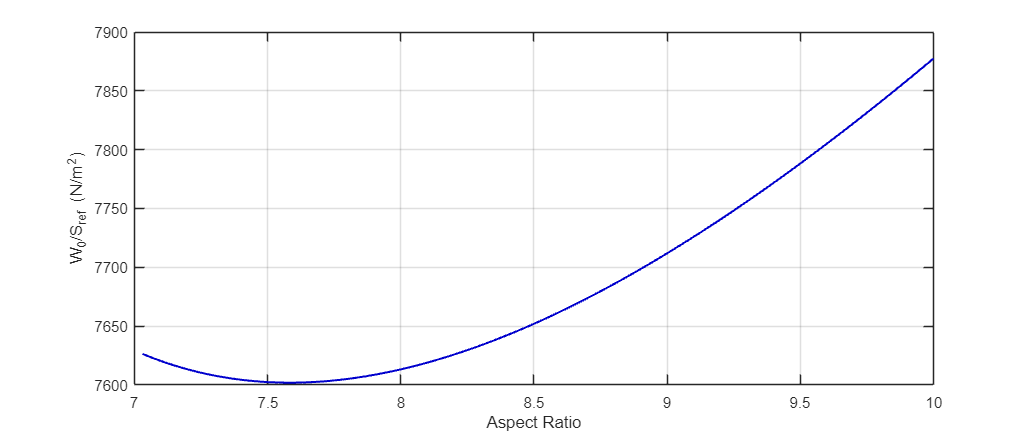

% Plot the comparision diagram

figure(1)

clf;

plot(AR_itr, W0_S, '-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25)

xlabel('Aspect Ratio'); 
ylabel('W_{0}/S_{ref} (N/m^{2})');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis


grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

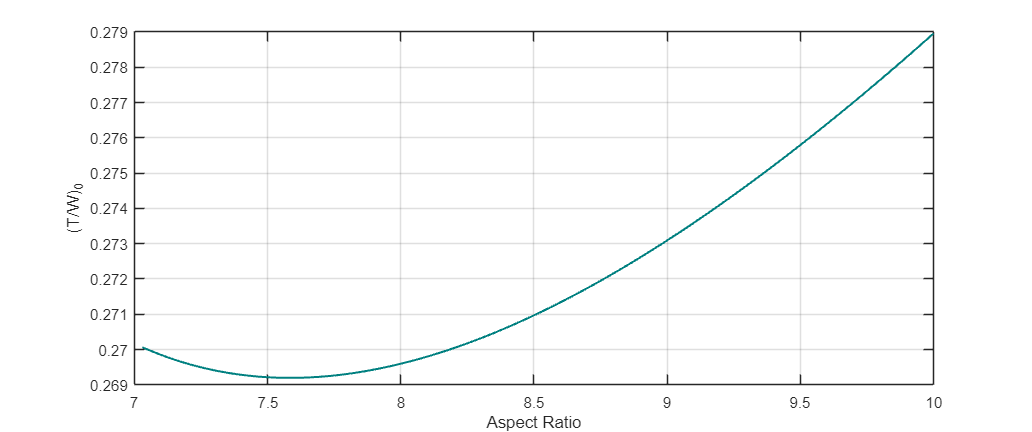

figure(2)

clf;

plot(AR_itr, T0_W0_itr, '-', 'Color',  [0/255 128/255 128/255], 'LineWidth', 1.25)

xlabel('Aspect Ratio'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis


grid on;                             % set the grid of the graph

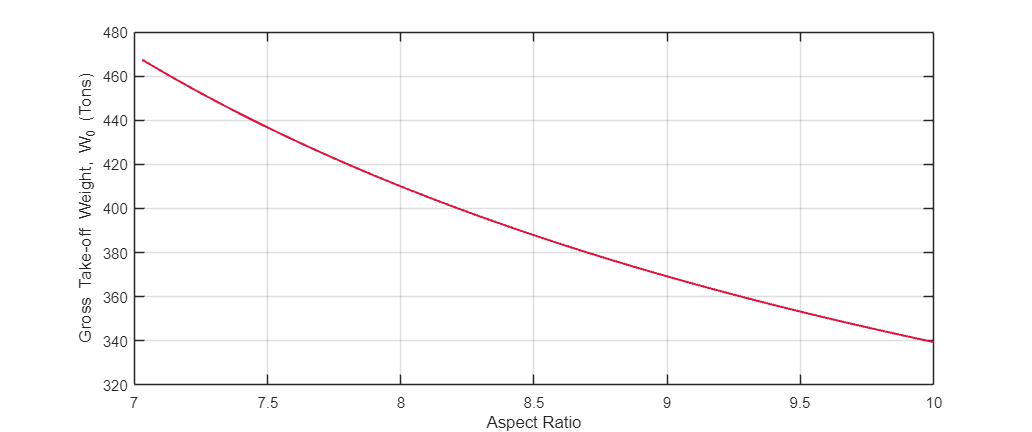

set(gcf, 'Position', [0 0 860 360]); % show plot with larger size
figure(3)

clf;

plot(AR_itr, W_0_itr ./ 1000, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25);
hold on

xlabel('Aspect Ratio'); 
ylabel('Gross Take-off Weight, W_{0} (Tons)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

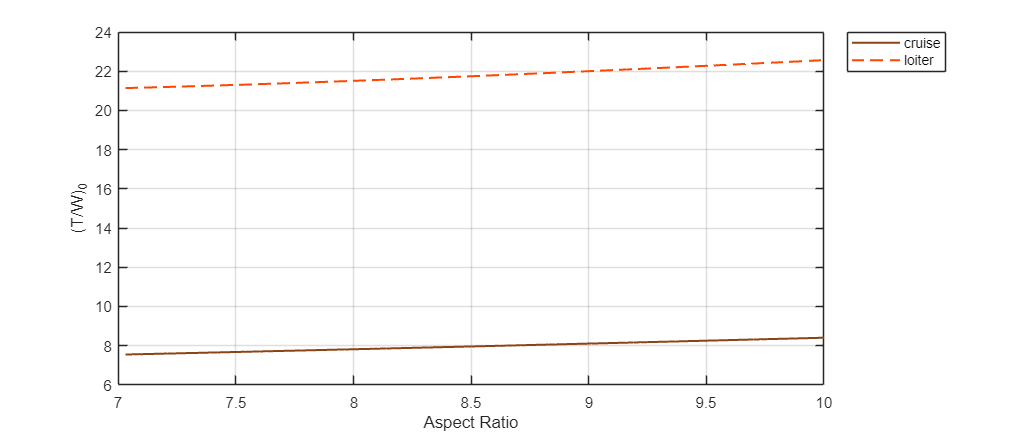


figure(5)

clf;

plot(AR_itr, LD_cruise_itr, '-', 'Color',  [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(AR_itr, LD_max_itr, '--', 'Color',  [255/255 69/255 0/255], 'LineWidth', 1.25)
hold off

legend('cruise', 'loiter', ...
       'Location', 'northeastoutside', 'NumColumns', 1, FontSize = 8.5)

xlabel('Aspect Ratio'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis


grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size